%    Copyright 2018 - 2019, Nikos Efthimiou
%
%    Licensed under the Apache License, Version 2.0 (the "License");
%    you may not use this file except in compliance with the License.
%    You may obtain a copy of the License at
%
%        http://www.apache.org/licenses/LICENSE-2.0
%
%    Unless required by applicable law or agreed to in writing, software
%    distributed under the License is distributed on an "AS IS" BASIS,
%    WITHOUT WARRANTIES OR CONDITIONS OF ANY KIND, either express or implied.
%    See the License for the specific language governing permissions and
%   limitations under the License.
%
%   01/2018: v.1.0

clear all; close all; clc;

## Convolution 2D: 

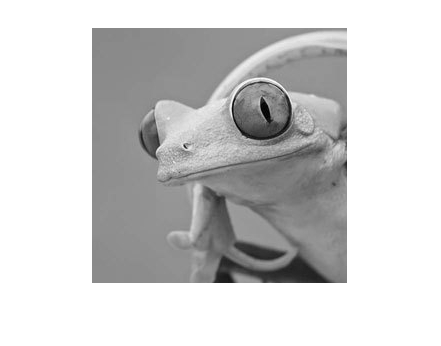

%Load an image
close all; clear all;
% Load an image
RGB = imread('frog.jpg');
%Get Intensity image
I = im2double(RGB);

% Now lets make the RGB values a single color.
I = rgb2gray(I);
imshow(I);

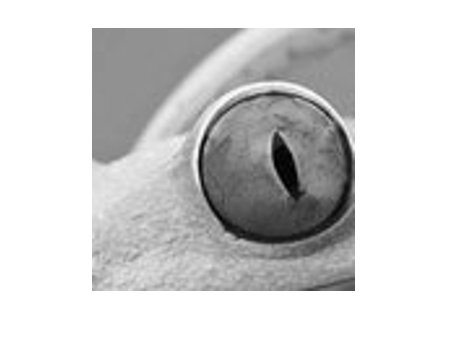


% Get a subspace of the image (detail)
D = I(30:130, 100:200);
% Resize the detail
D = imresize(D, 2.6);
imshow(D);

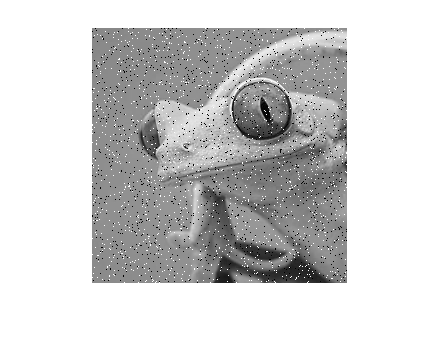


% Salt and Pepper noise
SP = imnoise(I, 'salt & pepper');
imshow(SP);

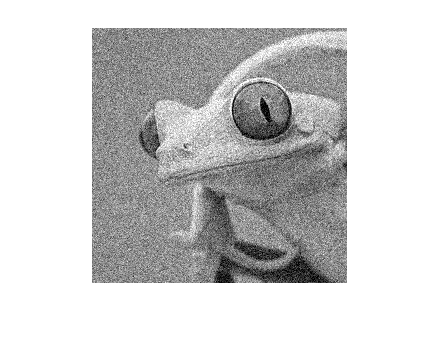

% Gaussian noise
G = imnoise(I, 'gaussian');
imshow(G);

## Mean filtering

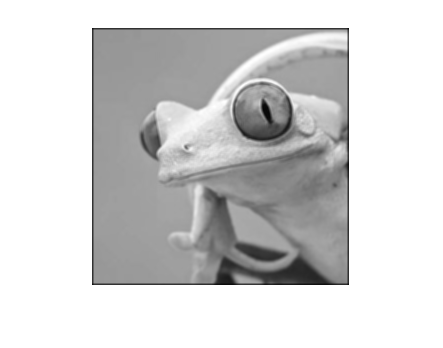

kernel_3x3 = [1 1 1;1 1 1;1 1 1]/9;

% Apply kernel 3x3
I_Sm3x3 = conv2(I, kernel_3x3);
% Normalize
I_Sm3x3 = I_Sm3x3 / max(max(I_Sm3x3));
% Display
imshow(I_Sm3x3),saveas(gcf,'orig_Sm3x3','epsc');

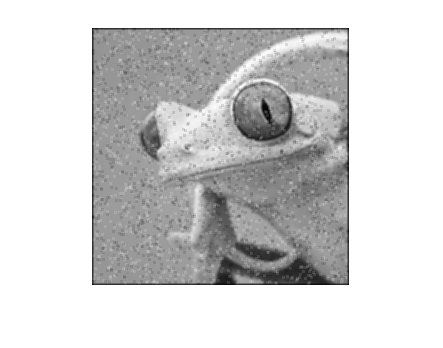


% SnP Apply kernel 3x3
SP_Sm3x3 = conv2(SP, kernel_3x3);
% Normalize
SP_Sm3x3 = SP_Sm3x3 / max(max(SP_Sm3x3));
% Display
imshow(SP_Sm3x3),saveas(gcf,'SP_Sm3x3','epsc');

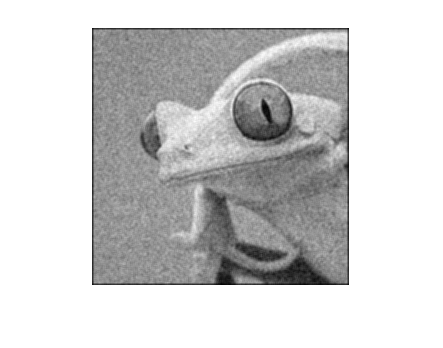


% Gaussian Apply kernel 3x3
G_Sm3x3 = conv2(G, kernel_3x3);
% Normalize
G_Sm3x3 = G_Sm3x3 / max(max(G_Sm3x3));
% Display
imshow(G_Sm3x3),saveas(gcf,'G_Sm3x3','epsc');

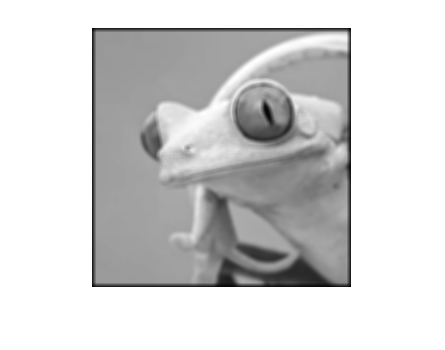

kernel_5x5 = [1 1 1 1 1;1 1 1 1 1;1 1 1 1 1; 1 1 1 1 1;1 1 1 1 1]/25;
kernel_7x7 = [1 1 1 1 1 1 1;1 1 1 1 1 1 1;1 1 1 1 1 1 1; 1 1 1 1 1 1 1;1 1 1 1 1 1 1;1 1 1 1 1 1 1;1 1 1 1 1 1 1]/49;
kernel_9x9 = [1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1; 1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1]/81;
kernel_11x11 = [1 1 1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1 1 1;
    1 1 1 1 1 1 1 1 1 1 1; 1 1 1 1 1 1 1 1 1 1 1;
    1 1 1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1 1 1;
    1 1 1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1 1 1;1 1 1 1 1 1 1 1 1 1 1]/121;

% Apply kernel 5x5
I_Sm5x5 = conv2(I, kernel_5x5);
% Normalize
I_Sm5x5 = I_Sm5x5 / max(max(I_Sm5x5));
% Display
imshow(I_Sm5x5),saveas(gcf,'orig_Sm5x5','epsc');

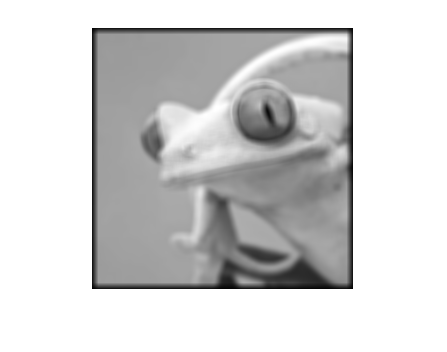


% Apply kernel 7x7
I_Sm7x7 = conv2(I, kernel_7x7);
% Normalize
I_Sm7x7 = I_Sm7x7 / max(max(I_Sm7x7));
% Display
imshow(I_Sm7x7),saveas(gcf,'orig_Sm7x7','epsc');

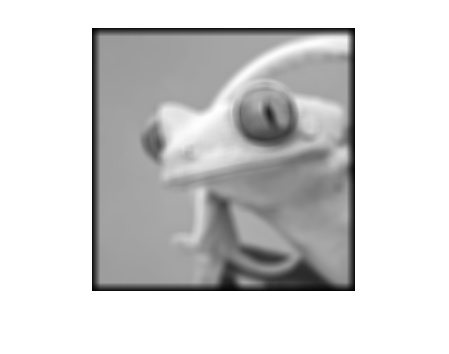


% Apply kernel 9x9
I_Sm9x9 = conv2(I, kernel_9x9);
% Normalize
I_Sm9x9 = I_Sm9x9 / max(max(I_Sm9x9));
% Display
imshow(I_Sm9x9),saveas(gcf,'orig_Sm9x9','epsc');

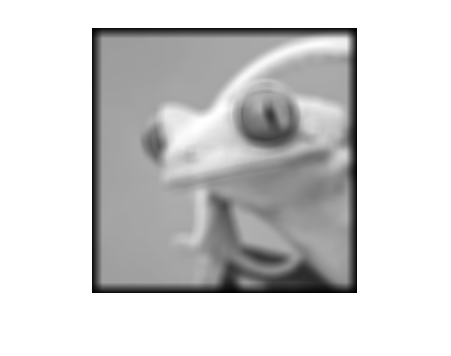


% Apply kernel 11x11
I_Sm11x11 = conv2(I, kernel_11x11);
% Normalize
I_Sm11x11 = I_Sm11x11 / max(max(I_Sm11x11));
% Display
imshow(I_Sm11x11),saveas(gcf,'orig_Sm11x11','epsc');

## Median Filters

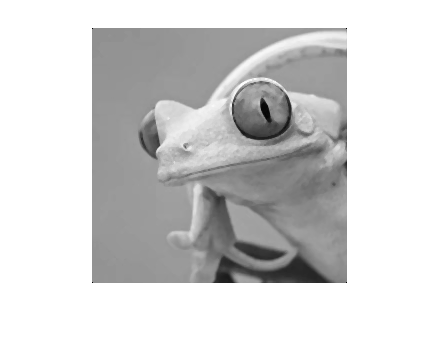

I_med3x3 = medfilt2(I,[3 3]);
I_med3x3 = I_med3x3 / max(max(I_med3x3));
% Display
imshow(I_med3x3),saveas(gcf,'orig_Med3x3','epsc');

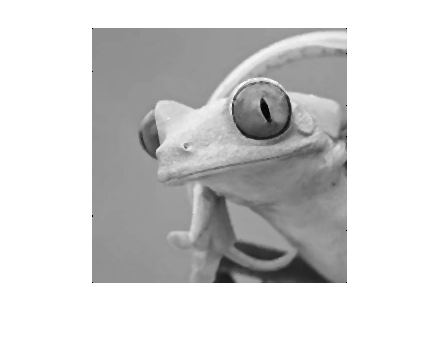


SP_med3x3 = medfilt2(SP,[3 3]);
SP_med3x3 = SP_med3x3 / max(max(SP_med3x3));
% Display
imshow(SP_med3x3),saveas(gcf,'SP_Med3x3','epsc');

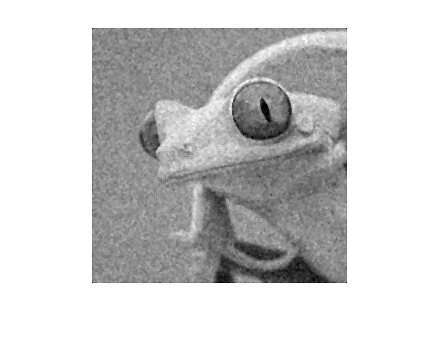


G_med3x3 = medfilt2(G,[3 3]);
G_med3x3 = G_med3x3 / max(max(G_med3x3));
% Display
imshow(G_med3x3),saveas(gcf,'G_Med3x3','epsc');




I_med3x3 = medfilt2(I,[3 3]);
I_med3x3 = I_med3x3 / max(max(I_med3x3));
% Display
imshow(I_med3x3),saveas(gcf,'orig_Med3x3','epsc');

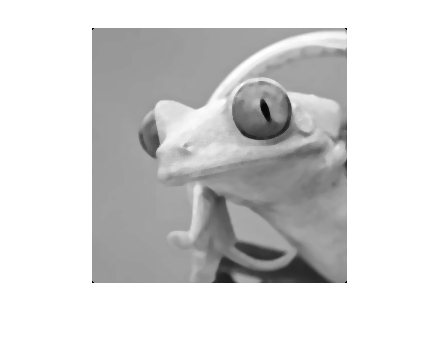


I_med5x5 = medfilt2(I,[5 5]);
I_med5x5 = I_med5x5 / max(max(I_med5x5));
% Display
imshow(I_med5x5),saveas(gcf,'orig_Med5x5','epsc');

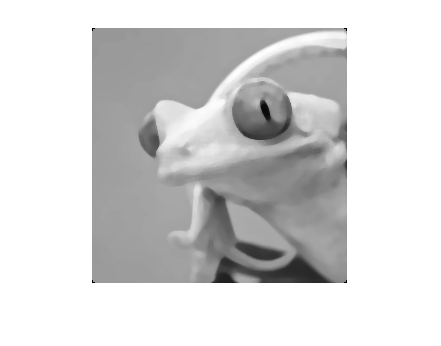


I_med7x7 = medfilt2(I,[7 7]);
I_med7x7 = I_med7x7 / max(max(I_med7x7));
% Display
imshow(I_med7x7),saveas(gcf,'orig_Med7x7','epsc');

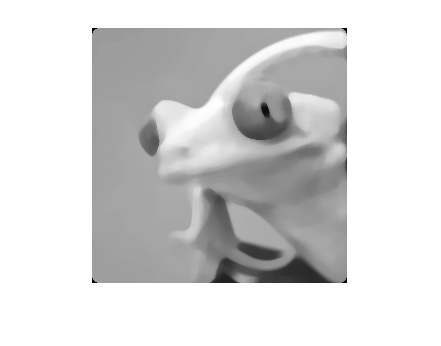


I_med11x11 = medfilt2(I,[11 11]);
I_med11x11 = I_med11x11 / max(max(I_med11x11));
% Display
imshow(I_med11x11),saveas(gcf,'orig_Med11x11','epsc');

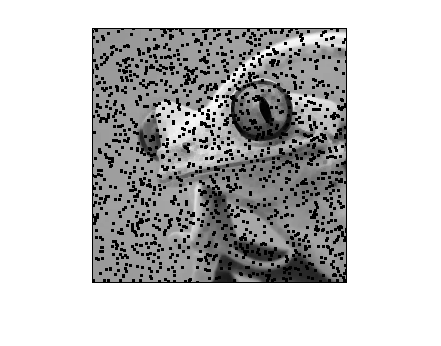

SP_ord_min3x3 = ordfilt2(SP,1,ones(3,3));
SP_ord_min3x3  = SP_ord_min3x3  / max(max(SP_ord_min3x3 ));
% Display
imshow(SP_ord_min3x3 ),saveas(gcf,'SP_Ord3x3','epsc');

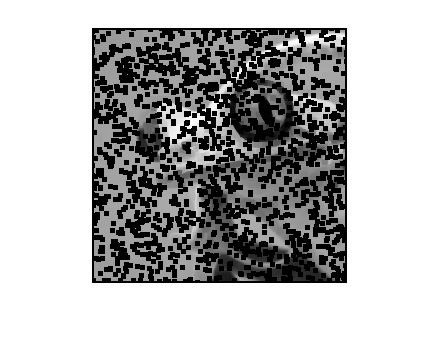


SP_ord_min5x5 = ordfilt2(SP,1,ones(5,5));
SP_ord_min5x5  = SP_ord_min5x5  / max(max(SP_ord_min5x5 ));
% Display
imshow(SP_ord_min5x5 ),saveas(gcf,'SP_Ord5x5','epsc');

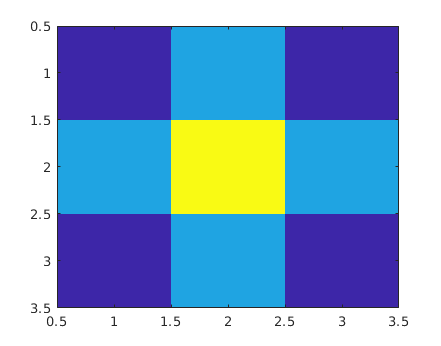

%Gaussian Filter
clear g_kernel3x3;
sigma = 1;
f = 1/(2*pi*sigma);

% 3x3
N = 1;
for (x = -N: 1: N)
    for (y = -N:1: N)
        g_kernel3x3(x+N+1,y+N+1) = f*exp(-(x^2+y^2)/(2*sigma^2));
    end
end
imagesc(g_kernel3x3),saveas(gcf,'G2D_3x3_1','epsc');

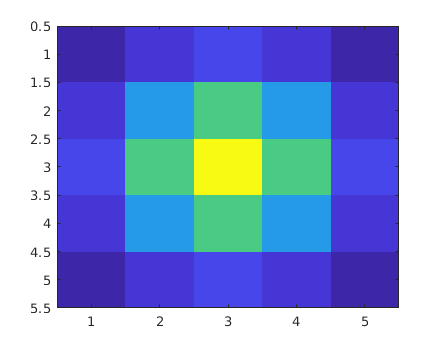


% 5x5
N = 2;
for (x = -N: 1: N)
    for (y = -N:1: N)
        g_kernel5x5(x+N+1,y+N+1) = f*exp(-(x^2+y^2)/(2*sigma^2));
    end
end
imagesc(g_kernel5x5),saveas(gcf,'G2D_5x5_1','epsc');

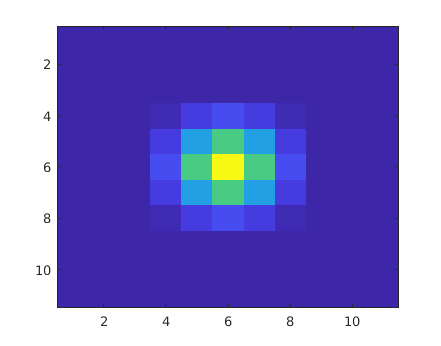


% 11x11
N = 5;
for (x = -N: 1: N)
    for (y = -N:1: N)
        g_kernel11x11(x+N+1,y+N+1) = f*exp(-(x^2+y^2)/(2*sigma^2));
    end
end
imagesc(g_kernel11x11),saveas(gcf,'G2D_11x11_1','epsc');

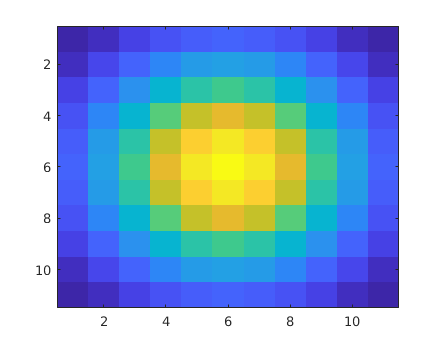


sigma = 3;
% 11x11
N = 5;
for (x = -N: 1: N)
    for (y = -N:1: N)
        g_kernel11x11_3(x+N+1,y+N+1) = f*exp(-(x^2+y^2)/(2*sigma^2));
    end
end
imagesc(g_kernel11x11_3),saveas(gcf,'G2D_11x11_3','epsc');

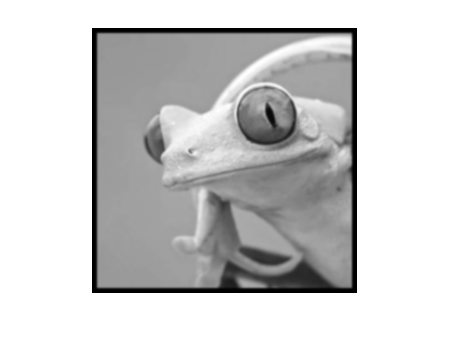

% sigma ==1
% Apply kernel 3x3
I_G11x11 = conv2(I, g_kernel11x11);
% Normalize
I_G11x11 = I_G11x11 / max(max(I_G11x11));
% Display
imshow(I_G11x11),saveas(gcf,'orig_G11x11','epsc');

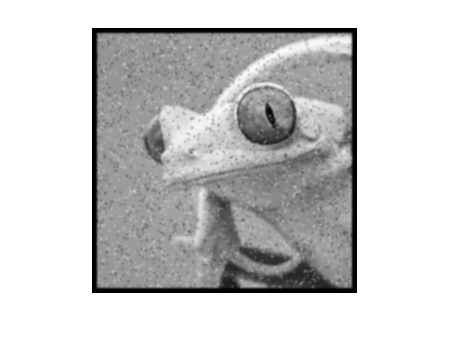


% SnP Apply kernel 3x3
SP_G11x11 = conv2(SP, g_kernel11x11);
% Normalize
SP_G11x11 = SP_G11x11 / max(max(SP_G11x11));
% Display
imshow(SP_G11x11),saveas(gcf,'SP_G11x11','epsc');

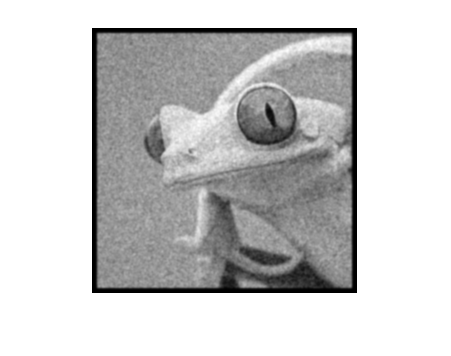


% Gaussian Apply kernel 11x11
G_G11x11 = conv2(G, g_kernel11x11);
G_G11x11u = G_G11x11; % Keep a  copy for later. 
% Normalize
G_G11x11 = G_G11x11 / max(max(G_G11x11));
% Display
imshow(G_G11x11),saveas(gcf,'G_G11x11','epsc');

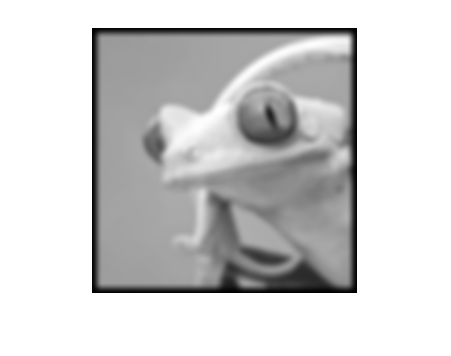


% sigma ==3
% Apply kernel 11x11 sigma 3
I_G11x11_3 = conv2(I, g_kernel11x11_3);
% Normalize
I_G11x11_3 = I_G11x11_3 / max(max(I_G11x11_3));
% Display
imshow(I_G11x11_3),saveas(gcf,'orig_G11x11_3','epsc');

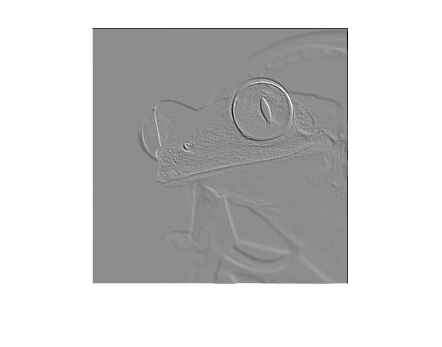

% Edge Detection - Roberts
rob_x = [0 -1; 1 0];
rob_y = [-1 0; 0 1];

%
I_Rb_x = conv2(I, rob_x);
% Remove negative values
b = min(min(I_Rb_x));
if (b<0.0)
    I_Rb_x = I_Rb_x - b;
end
% Normalize
I_Rb_x = I_Rb_x / max(max(I_Rb_x));
% Display
imshow(I_Rb_x),saveas(gcf,'I_Rb_x','epsc');

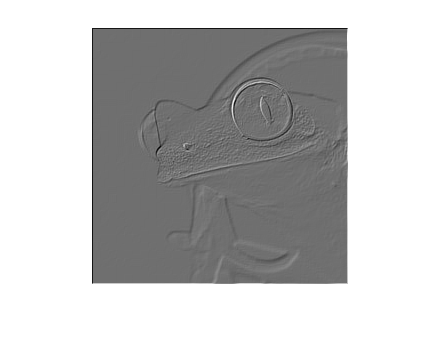


%
I_Rb_y = conv2(I, rob_y);
% Remove negative values
b = min(min(I_Rb_y));
if (b<0.0)
    I_Rb_y = I_Rb_y - b;
end
% Normalize
I_Rb_y = I_Rb_y / max(max(I_Rb_y));
% Display
imshow(I_Rb_y),saveas(gcf,'I_Rb_y','epsc');

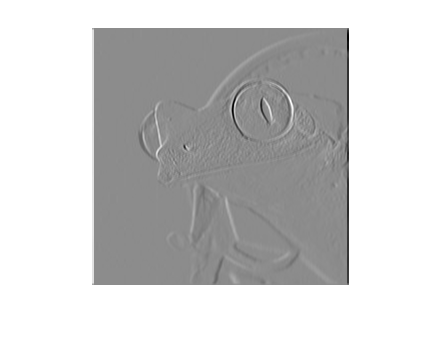

% Edge Detection - Prewitt
prew = [1 0 -1; 1 0 -1;1 0 -1];
sob = [1 0 -1; 2 0 -2;1 0 -1];

%
I_prew_x = conv2(I, prew);
% Remove negative values
b = min(min(I_prew_x));
if (b<0.0)
    I_prew_x = I_prew_x - b;
end
% Normalize
I_prew_x = I_prew_x / max(max(I_prew_x));
% Display
imshow(I_prew_x),saveas(gcf,'I_prew_x','epsc');

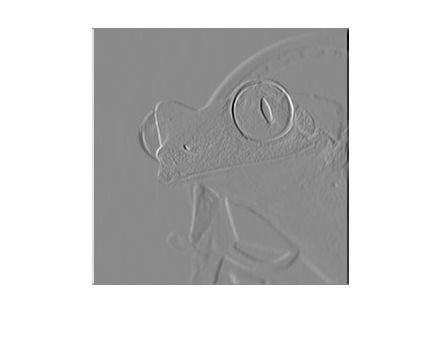


%
I_sob_x = conv2(I, sob);
% Remove negative values
b = min(min(I_sob_x));
if (b<0.0)
    I_sob_x = I_sob_x - b;
end
% Normalize
I_sob_x = I_sob_x / max(max(I_sob_x));
% Display
imshow(I_sob_x),saveas(gcf,'I_sob_x','epsc');

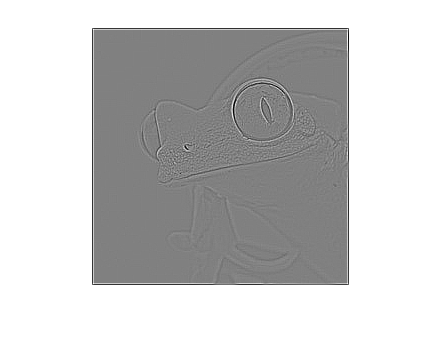

% Laplacian
lap = [-1 -1 -1; -1 8 -1;-1 -1 -1];
I_lap = conv2(I, lap);
% Remove negative values
b = min(min(I_lap));
if (b<0.0)
    I_lap= I_lap - b;
end
% Normalize
I_lap = I_lap / max(max(I_lap));
% Display
imshow(I_lap),saveas(gcf,'I_lap','epsc');

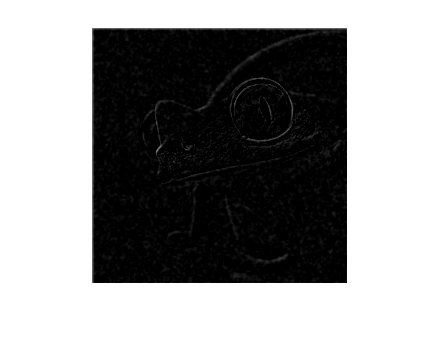


% Unsharp Laplacian
I_unsharp = I - G_G11x11u(5:259, 5:259);
imshow(I_unsharp),saveas(gcf,'I_unsharp','epsc');

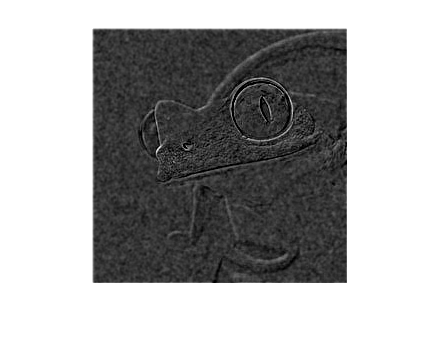


k = 3;
I_lap_un = I_lap(2:256, 2:256) + k*I_unsharp ;
% Remove negative values
% b = min(min(I_lap));
% if (b<0.0)
%     I_lap_un=I_lap_u - b;
% end
% Normalize
I_lap_un = I_lap_un / max(max(I_lap_un));
% Display
imshow(I_lap_un),saveas(gcf,'I_lap_un','epsc');

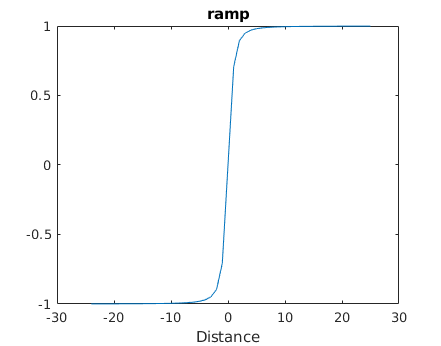

% Lets create an edge
N = 50; % Number of points in our figure
x = -24:1:25;

ramp = 0;

for i = 1: N
    ramp(i) = x(i) / sqrt( 1 +x(i)^2) ;
end

plot(x,ramp);
xlabel('Distance')
title('ramp')

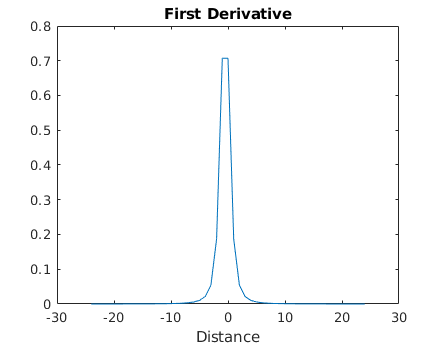


%First derivative is the difference between adjusent values.
for i = 1: N-1
    first(i) = (ramp(i+1)-ramp(i)) / ((x(i+1) - x(i)));
end

plot(-24:1:24 ,first);
xlabel('Distance')
title('First Derivative')

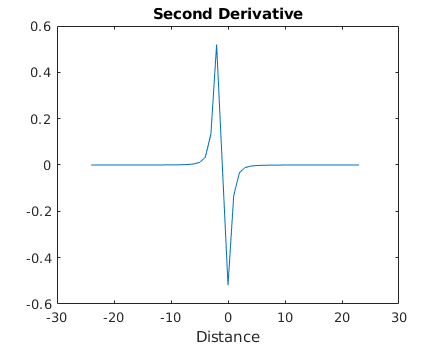


%First derivative is the difference between adjusent values.
sec = 0;
for i = 1: N-2
    sec(i) = (first(i+1)-first(i)) / ((x(i+1) - x(i)));
end

plot(-24:1:23 ,sec);
xlabel('Distance')
title('Second Derivative')